# Resolución de Casos 5

### Pregunta 1

Demostrar que $R_0 =Q_0^t A_0$.

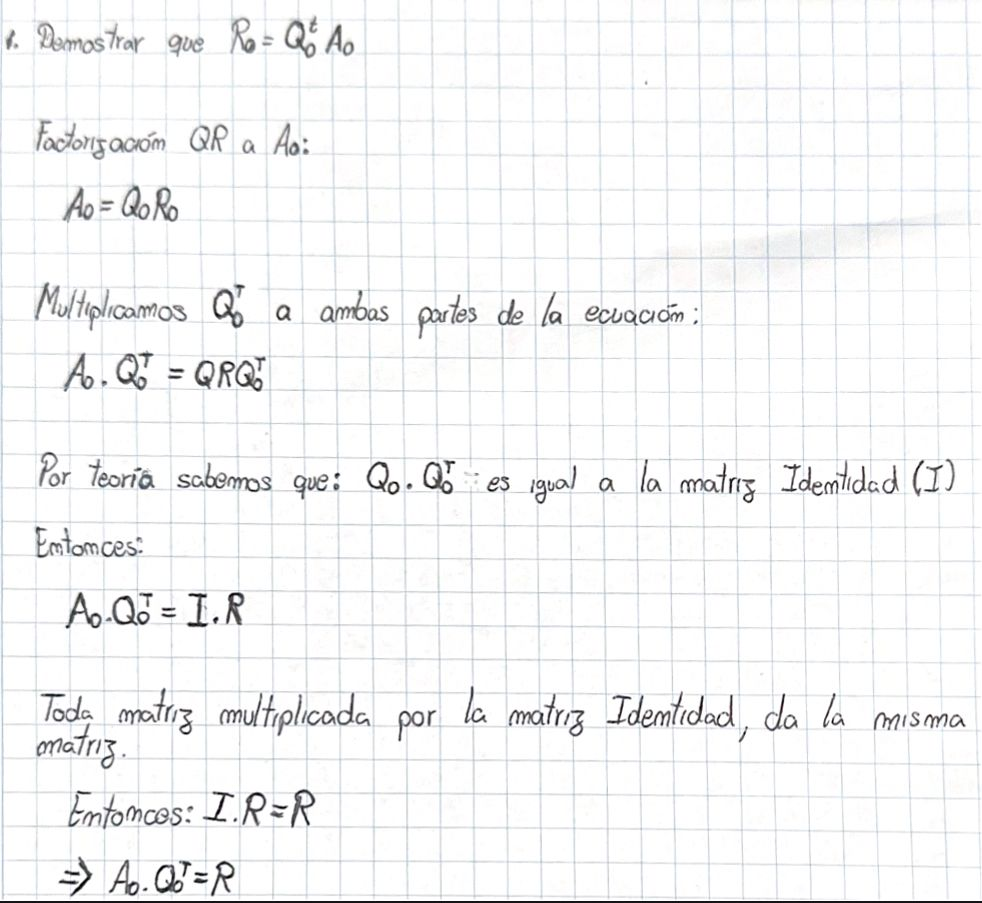

### Pregunta 2

Llamamos $A_1 =R_0 Q_0 =Q_0^t A_0 Q_0$. En general definimos, si $A_k =Q_{k\;} R_k$, entonces $A_{k+1} =R_k Q_k$. Si $A_0 =\left\lbrack \begin{array}{ccc}
2 & 1 & 0\\
1 & 3 & 1\\
0 & 1 & 4
\end{array}\right\rbrack$, hallar $A_7$, $A_8$ y $A_9$.

Declaramos $A_0$ y obtenemos de forma iterativa los valores de $A_k$.

A_0 = [2 1 0 ; 1 3 1 ; 0 1 4];
A_k = A_0;

for i = 1:9
    fprintf("A" + i + ":")
    [Q_k, R_k] = qr(A_k); % Factorización QR
    A_k = R_k * Q_k % Transformación A_k + 1 = R_k * Q_k
end

A1:

A_k =     3.0000    1.0954   -0.0000
    1.0954    3.0000   -1.3416
         0   -1.3416    3.0000


A2:

A_k =     3.7059    0.9558    0.0000
    0.9558    3.5214    0.9738
         0    0.9738    1.7727


A3:

A_k =     4.1566    0.8284   -0.0000
    0.8284    3.4880   -0.4162
         0   -0.4162    1.3553


A4:

A_k =     4.4487    0.6422    0.0000
    0.6422    3.2690    0.1638
         0    0.1638    1.2823


A5:

A_k =     4.6062    0.4497   -0.0000
    0.4497    3.1234   -0.0662
         0   -0.0662    1.2704


A6:

A_k =     4.6792    0.2979    0.0000
    0.2979    3.0524    0.0274
         0    0.0274    1.2684


A7:

A_k =     4.7104    0.1924   -0.0000
    0.1924    3.0216   -0.0115
         0   -0.0115    1.2680


A8:

A_k =     4.7233    0.1229    0.0000
    0.1229    3.0087    0.0048
         0    0.0048    1.2680


A9:

A_k =     4.7285    0.0781   -0.0000
    0.0781    3.0035   -0.0020
         0   -0.0020    1.2680


### Pregunta 3

Verificar que la diagonal de la matriz $A_9$ se aproxima a los vectores de A. Comparar en el matlab mediante el uso del comando eig.

Volvemos a realizar la iteración que usamos en la pregunta 3 para obtener $A_9$.

A_k = A_0;

for i = 1:9
    [Q_k, R_k] = qr(A_k);
    A_k = R_k * Q_k;
end

Ahora, calculamos los autovalores de $A$, y extraemos la diagonal de $A_9$.

eigA = eig(A_0)

eigA =     1.2679
    3.0000
    4.7321


diagA9 = diag(A_k)

diagA9 =     4.7285
    3.0035
    1.2680


Comparamos los autovalores de $A$ con la diagonal de $A_9$.

Autovalores de $A$:

eigA

eigA =     1.2679
    3.0000
    4.7321


Diagonal de $A_9$:

diagA9

diagA9 =     4.7285
    3.0035
    1.2680
